# Alkım Ege Akarsu, 21901461 | CS 484 | HW3

## Part 1

% Image storage
imgs = cell(1, 10);

% Image label storage
img_labels = cell(1, 10);

% Get superpixel labels
for i = 1:10
    imgs{i} = imread(sprintf('%d.jpg', i));
    [labels, numlabels] = slicomex(imgs{i}, 450); % 305, 450 (all images need to have the same number of superpixels)
    img_labels{i} = cast(labels, "uint16");
    numlabels
end

numlabels = int32
442

numlabels = int32
442

numlabels = int32
442

numlabels = int32
442

numlabels = int32
442

numlabels = int32
442

numlabels = int32
442

numlabels = int32
442

numlabels = int32
442

numlabels = int32
442

## Part 2

% Grayscale image storage
imgs_grayscale = cell(1, 10);

% Convert images to grayscale
for i = 1:10
    imgs_grayscale{i} = rgb2gray(imgs{i});
end

% Define Gabor filter bank
filter_bank = gabor([2, 4, 8, 16, 32], [0, 36, 72, 108, 144]);

% Image gabor storage
img_gabors = cell(1, 10);

% Get Gabor filtered images
for i = 1:10
    [img_gabors{i}, temp] = imgaborfilt(imgs_grayscale{i}, filter_bank);
end

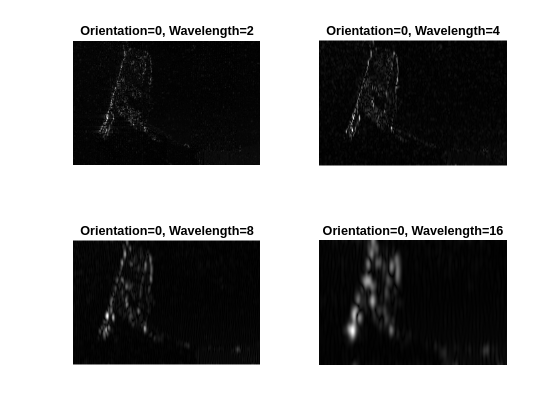


% Display some gabor filtered results
im_num = 8;
figure
subplot(2,2,1);
for p = 1:4
    subplot(2,2,p)
    imshow(img_gabors{im_num}(:,:,p),[]);
    theta = filter_bank(p).Orientation;
    lambda = filter_bank(p).Wavelength;
    title(sprintf('Orientation=%d, Wavelength=%d',theta,lambda));
end

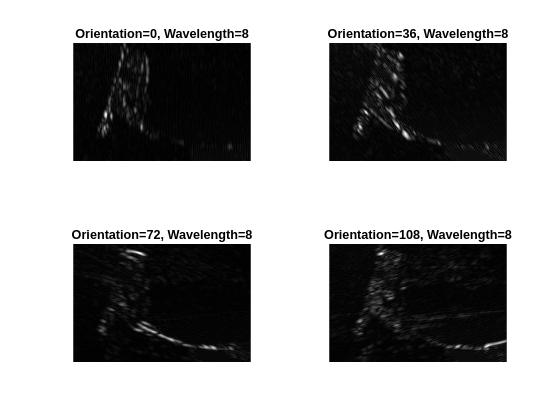


figure
tiledlayout(2,2);
for p = 3:5:19
    nexttile;
    imshow(img_gabors{im_num}(:,:,p),[]);
    theta = filter_bank(p).Orientation;
    lambda = filter_bank(p).Wavelength;
    title(sprintf('Orientation=%d, Wavelength=%d',theta,lambda));
end

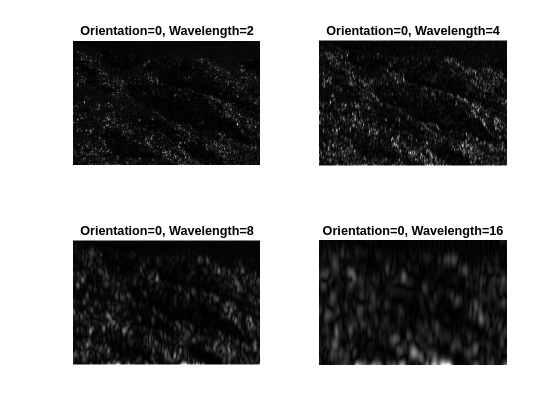


im_num = 10;
figure
subplot(2,2,1);
for p = 1:4
    subplot(2,2,p)
    imshow(img_gabors{im_num}(:,:,p),[]);
    theta = filter_bank(p).Orientation;
    lambda = filter_bank(p).Wavelength;
    title(sprintf('Orientation=%d, Wavelength=%d',theta,lambda));
end

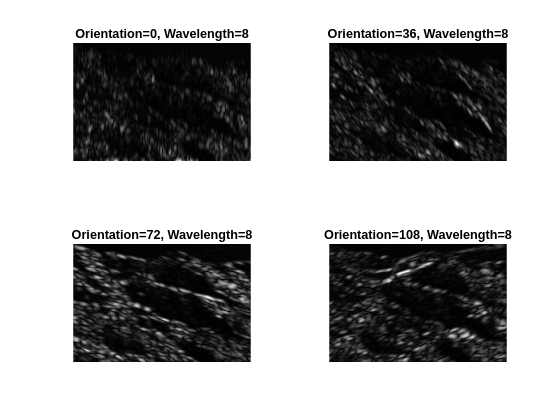


figure
tiledlayout(2,2);
for p = 3:5:19
    nexttile;
    imshow(img_gabors{im_num}(:,:,p),[]);
    theta = filter_bank(p).Orientation;
    lambda = filter_bank(p).Wavelength;
    title(sprintf('Orientation=%d, Wavelength=%d',theta,lambda));
end

Save neccessary files to transfer to python.

save('variables.mat', "img_gabors", "img_labels")